load tupleCount-tg-s044-MercuryErrorLog.txt

load tupleCount-tg-s038-MercuryErrorLog.txt

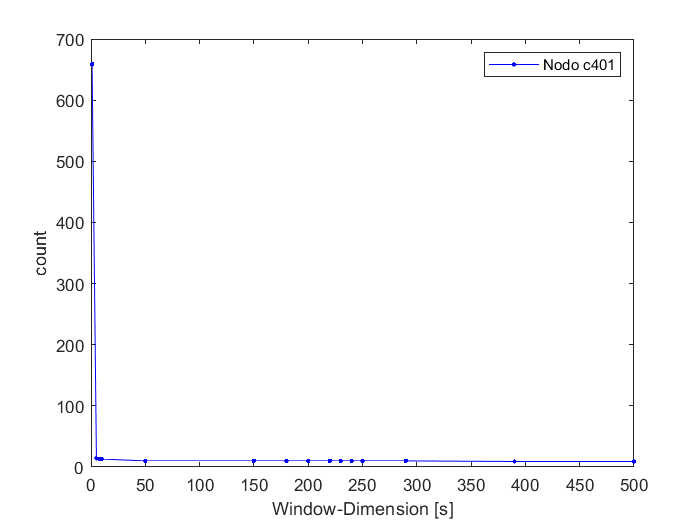

plot(s044(:,1), s044(:,2), '.-r');
% ,s044(:,1), s044(:,2), '.-r'
xlabel('Window-Dimension [s]');
legend('Nodo c401')
ylabel('count');

load tupling_tg-s038-MercuryErrorLog-5\interarrivals.txt

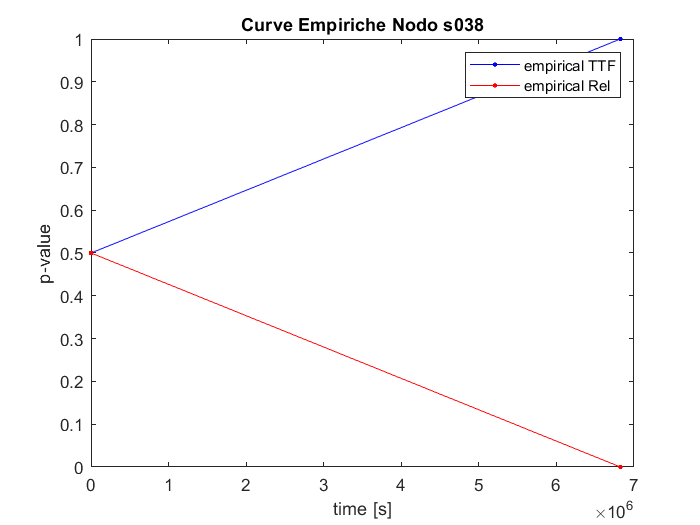

[y,t] = cdfcalc(interarrivals);
empTTF=y(2:size(y,1));
empRel=1-empTTF;
plot(t,empTTF,'.-b',t,empRel,'.-r');
xlabel('time [s]'); ylabel('p-value'); title('Curve Empiriche Nodo s038')
legend('empirical TTF', 'empirical Rel');